hold off;
counter = 0;
ii = 14

ii = 14

hold on;
    counter = counter + 1

counter = 1

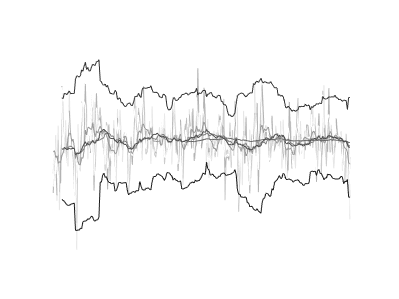

     plot(dataTable.Open(ii:ii + inputWindowSize), 'Color', [0.9 0.9 0.9]);
     plot(dataTable.High(ii:ii + inputWindowSize), 'Color', [0.8 0.8 0.8]);
     plot(dataTable.Low(ii:ii + inputWindowSize), 'Color', [0.7 0.7 0.7]);
    plot(dataTable.Close(ii:ii + inputWindowSize), 'Color', [1 1 1]);
    % add indocators
    plot(ma1(ii:ii + inputWindowSize), 'Color', [0.6 0.6 0.6]);
    plot(ma2(ii:ii + inputWindowSize), 'Color', [0.5 0.5 0.5]);
    plot(ma3(ii:ii + inputWindowSize), 'Color', [0.4 0.4 0.4]);
    plot(boll(ii:ii + inputWindowSize,1), 'Color', [0.3 0.3 0.3]);
    plot(boll(ii:ii + inputWindowSize,2), 'Color', [0.2 0.2 0.2]);
    plot(boll(ii:ii + inputWindowSize,3), 'Color', [0.1 0.1 0.1]);
%     
    x0=10;
    y0=10;
    width=1280;
    height=768;

    axis off
    exportgraphics(gca, "image" + counter + ".png","BackgroundColor","black","Resolution",300,"Colorspace","gray");

%     imwrite(rgb2gray(gca), "image" + counter + ".png");
%   set(gcf,'position',[x0,y0,width,height], 'Color', [0 0 0]);
%    saveas(gca, "image" + counter + ".bmp", 'bmp256');
%     if (signals(ii+1+ inputWindowSize) == 1)
%         movefile("image" + counter + ".png", "AUDUSD/Buy");
%     elseif (signals(ii+1+ inputWindowSize) == -1)
%         movefile("image" + counter + ".png", "AUDUSD/Sell");
%     else
%         movefile("image" + counter + ".png", "AUDUSD/Hold");
%     end
%     close;